clear all;
clc

# **Fase 1:**

**FUERZAS:**

gravedad = 9.81;          % Aceleración debido a la gravedad (m/s^2)
masa = 70;                % Masa del saltador en kilogramos
F = masa * gravedad;   % Fuerza de gravedad actuando sobre el saltador (N)

**CONDICIONES INICIALES:**

tiempo = 0:0.01:2.58;   % Vector de tiempo en segundos (desde 0 hasta 10 segundos con incrementos de 0.1)
vi = 0;             % Velocidad inicial del saltador (m/s)
yi = 0;             % Posición inicial del saltador (m)
LC = 32.63;         % Longitud de la cuerda

**FORMULANDO LA ED:**


$$\textrm{aceleración}:\;y\prime \prime \left(t\right)=\textrm{gravedad}$$


**INTEGRANDO ACELERACIÓN:**


$$\textrm{velocidad}\;\;\;:\;y\prime \left(t\right)\;\;=\textrm{gt}+\textrm{C1}$$


**EVALUACIÓN EN **$y\prime \left(0\right)$**:  **

C1 = gravedad * 0 - vi;
disp("el valor de C1 es: " + C1)

el valor de C1 es: 0


**NUESTRA FUNCIÓN DE VELOCIDAD QUEDA:**

v_t = gravedad * tiempo;
disp("Las soluciones para la velocidad son: " + v_t)

    "Las soluciones para la velocidad son: 0"    "Las soluciones para la velocidad son: 0.0981"    "Las soluciones para la velocidad son: 0.1962"    "Las soluciones para la velocidad son: 0.2943"    "Las soluciones para la velocidad son: 0.3924"    "Las soluciones para la velocidad son: 0.4905"    "Las soluciones para la velocidad son: 0.5886"    "Las soluciones para la velocidad son: 0.6867"    "Las soluciones para la velocidad son: 0.7848"    "Las soluciones para la velocidad son: 0.8829"    "Las soluciones para la velocidad son: 0.981"    "Las soluciones para la velocidad son: 1.0791"    "Las soluciones para la velocidad son: 1.1772"    "Las soluciones para la velocidad son: 1.2753"    "Las soluciones para la velocidad son: 1.3734"    "Las soluciones para la velocidad son: 1.4715"    "Las soluciones para la velocidad son: 1.5696"    "Las soluciones para la velocidad son: 1.6677"    "Las soluciones para la velocidad son: 1.7658"    "Las soluciones para la velocidad son: 1.8639"    "L

**TEGRAMOS NUESTRA FUNCIÓN VELOCIDAD:**

$\to \int \mathrm{velocidad}=\int \mathrm{gt}=\frac{1}{2}\left({\mathrm{gt}}^2 \right)$ +  C1 (t)  +  C2 = y(t)

**EVALUACIÓN EN **$y\left(0\right)$**:  **

C2 = -gravedad * 0^2 - LC;
disp("el valor de C2 es: " + C2);

el valor de C2 es: -32.63


**OBTENEMOS NUESTRA FUNCIÓN DE POSICIÓN**

y_t = (0.5 * gravedad * tiempo.^2) + C2;
disp("Las posiciones son: " + y_t)

    "Las posiciones son: -32.63"    "Las posiciones son: -32.6295"    "Las posiciones son: -32.628"    "Las posiciones son: -32.6256"    "Las posiciones son: -32.6222"    "Las posiciones son: -32.6177"    "Las posiciones son: -32.6123"    "Las posiciones son: -32.606"    "Las posiciones son: -32.5986"    "Las posiciones son: -32.5903"    "Las posiciones son: -32.581"    "Las posiciones son: -32.5706"    "Las posiciones son: -32.5594"    "Las posiciones son: -32.5471"    "Las posiciones son: -32.5339"    "Las posiciones son: -32.5196"    "Las posiciones son: -32.5044"    "Las posiciones son: -32.4882"    "Las posiciones son: -32.4711"    "Las posiciones son: -32.4529"    "Las posiciones son: -32.4338"    "Las posiciones son: -32.4137"    "Las posiciones son: -32.3926"    "Las posiciones son: -32.3705"    "Las posiciones son: -32.3475"    "Las posiciones son: -32.3234"    "Las posiciones son: -32.2984"    "Las posiciones son: -32.2724"    "Las posiciones son: -32.2454"    "Las posiciones

**ECUACIÓN DIFERENCIAL:**

$\frac{{\mathrm{dt}}^2 }{d^2 y}$=-k(y') - mg

**RESULTADOS:**

% Parámetros
gravedad = 9.81; % Aceleración debido a la gravedad (m/s^2)
masa = 70; % Masa del saltador en kilogramos
LC = 32.63; % Longitud de la cuerda (m)
F_gravedad = masa * gravedad; % Fuerza de gravedad (N)

% Condiciones iniciales
tiempo = 0:0.01:2.58; % Vector de tiempo (segundos)
vi = 0; % Velocidad inicial (m/s)
yi = 0; % Posición inicial (m)

% Cálculo de la constante C1 para la velocidad
C1 = gravedad * 0 - vi;
disp("El valor de C1 es: " + C1);

El valor de C1 es: 0



% Función de velocidad en el tiempo
v_t = gravedad * tiempo; % No hay resistencia en esta fase
disp("Las soluciones para la velocidad son: ");

Las soluciones para la velocidad son: 


disp(v_t);

         0    0.0981    0.1962    0.2943    0.3924    0.4905    0.5886    0.6867    0.7848    0.8829    0.9810    1.0791    1.1772    1.2753    1.3734    1.4715    1.5696    1.6677    1.7658    1.8639    1.9620    2.0601    2.1582    2.2563    2.3544    2.4525    2.5506    2.6487    2.7468    2.8449    2.9430    3.0411    3.1392    3.2373    3.3354    3.4335    3.5316    3.6297    3.7278    3.8259    3.9240    4.0221    4.1202    4.2183    4.3164    4.4145    4.5126    4.6107    4.7088    4.8069    4.9050    5.0031    5.1012    5.1993    5.2974    5.3955    5.4936    5.5917    5.6898    5.7879    5.8860    5.9841    6.0822    6.1803    6.2784    6.3765    6.4746    6.5727    6.6708    6.7689    6.8670    6.9651    7.0632    7.1613    7.2594    7.3575    7.4556    7.5537    7.6518    7.7499    7.8480    7.9461    8.0442    8.1423    8.2404    8.3385    8.4366    8.5347    8.6328    8.7309    8.8290    8.9271    9.0252    9.1233    9.2214    9.3195    9.4176    9.5157    9.6138    9.7119


% Integrando la velocidad para obtener la posición
% Cálculo de la constante C2 para la posición
C2 = -gravedad * 0^2 - LC;
disp("El valor de C2 es: " + C2);

El valor de C2 es: -32.63


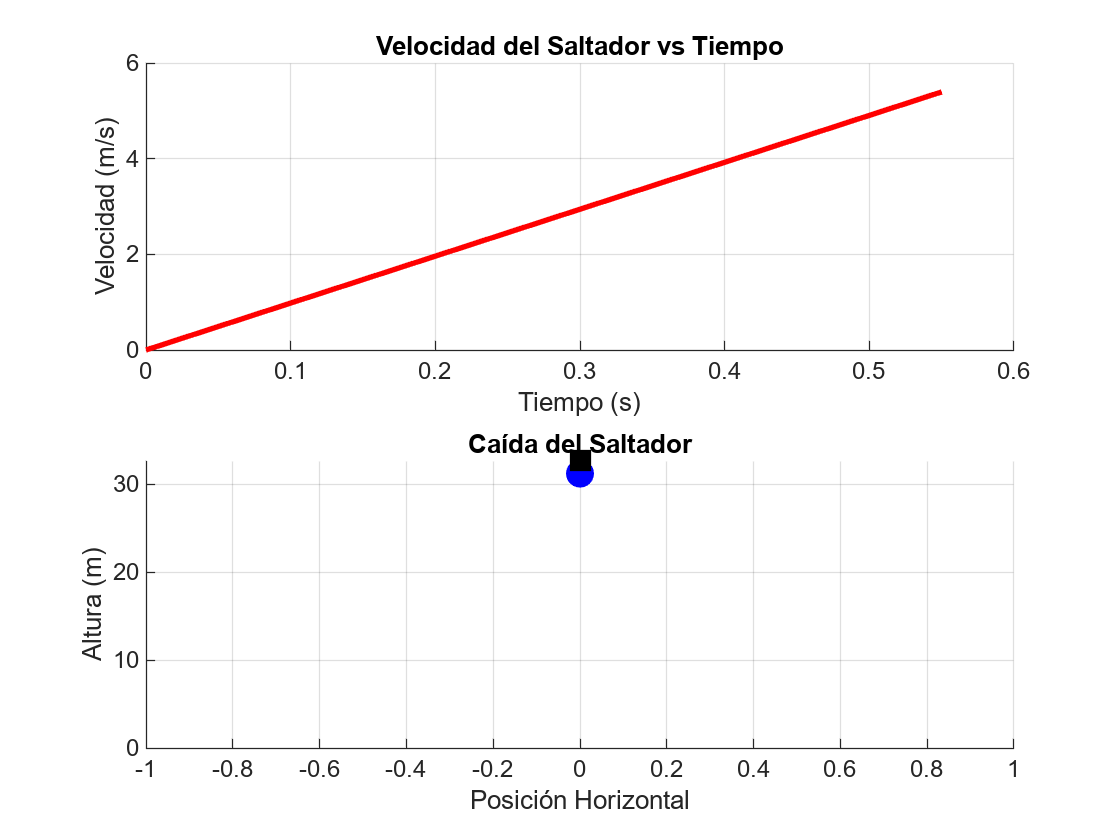


% Función de posición en el tiempo (invirtiendo la dirección de la altura)
y_t = LC - (0.5 * gravedad * tiempo.^2); % El saltador parte desde la altura de la cuerda

% Gráfica animada del punto en caída
figure;
h1 = subplot(2,1,1); % Gráfico para velocidad
h2 = subplot(2,1,2); % Gráfico para posición y caída

% Configuración de las gráficas
subplot(h1);
title('Velocidad del Saltador vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
grid on;
hold on;

subplot(h2);
title('Caída del Saltador');
xlabel('Posición Horizontal');
ylabel('Altura (m)');
ylim([0 LC]); % Límite de altura de 0 a la longitud de la cuerda (inversión)
xlim([-1 1]); % Eje horizontal fijo
hold on;
grid on;

% Dibujar la plataforma inicial
plot(0, LC, 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k'); % Plataforma en la parte superior

% Animación del punto en caída
for i = 1:length(tiempo)
    % Actualizando gráfica de velocidad
    subplot(h1);
    plot(tiempo(1:i), v_t(1:i), 'r', 'LineWidth', 2); % Velocidad
    pause(0.05); % Pausa para hacer la animación más lenta

    % Actualizando la caída del saltador como un punto
    subplot(h2);
    cla; % Limpiar el gráfico antes de dibujar el siguiente punto
    plot(0, y_t(i), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b'); % Saltador como punto
    plot(0, LC, 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k'); % Plataforma fija
    pause(0.05); % Pausa para hacer la animación más lenta
    
    drawnow; % Actualizar los gráficos en tiempo real
end


hold off;



# **Fase 2:**

**FUERZAS:**

gravedad = 9.81;          % Aceleración debido a la gravedad (m/s^2)
masa = 70;                % Masa del saltador en kilogramos
F = masa * gravedad;   % Fuerza de gravedad actuando sobre el saltador (N)

**CONDICIONES INICIALES:**

tiempo = 0:0.1:10;  % Vector de tiempo en segundos (desde 0 hasta 10 segundos con incrementos de 0.1)
yi = 0;             % Posición inicial del saltador (m)
disp('velocidad: ' + v_t(end))

**FORMULANDO LA ED:**


$$y\left(\textrm{t0}\right)=\textrm{L0}$$


**FUERZA ELÁSTICA:**


$$\textrm{Fe}=-k\left(y\left(t\right)-\textrm{L0}\right)$$


$k$** ES LA CONSTANTE DE LA CUERDA (N/m). **

L0 = -C2;
Fe = F;
k = (y_t-L0)/Fe

$\textrm{L0}$** ES LA LONGITUD DE LA CUERDA EN REPOSO (m) . **

$y\left(t\right)$** ES LA POSICIÓN EN FUNCIÓN DEL TIEMPO (s)**

**FUERZA NETA:**


$$\textrm{Fn}=\textrm{ma}=-k\left(y\left(t\right)-\textrm{L0}\right)\;\;\;\to \;\;\;\textrm{Fn}=\textrm{ma}+\textrm{ky}\left(t\right)-\textrm{kL0}$$


**REPRESENTADA DE OTRA FORMA:**


$${{\textrm{my}}^{\prime } }^{\prime } +\textrm{ky}=\textrm{mg}+\textrm{kL0}$$



$$y\prime \prime +\left(\frac{k}{m}\right)y=g+\left(\frac{k}{m}\right)\textrm{L0}$$


**OBTENDREMOS **$\textrm{yc}$

**SI **${y^{\prime } }^{\prime } +\left(\frac{k}{m}\right)y\;=0\;\;\to \;\;r^2 =\sqrt{\frac{k}{m}\;i}\;\;\;\;\to \alpha =0\;y\;\beta =\sqrt{\frac{k}{m}}$ =$\omega$

**ENTONCES **$\textrm{yc}=C_1 \cos \left(\omega t\right)+C_2 \sin \left(\omega t\right)$

w = sqrt(k/masa)

**OBTENDREMOS **$\textrm{yp}$ **CON VALORES CONSTANTES**

**SI **$\mathrm{yp}=g+\left(\frac{k}{m}\right)\mathrm{L0}\;\;\;\to \mathrm{yp}=g+\omega^2$L0


$$y\left(t\right)=C_1 \cos \left(\omega t\right)+C_2 \sin \left(\omega t\right)+g+\omega^2 \mathrm{L0}\;$$


**EVALUAMOS EN **$y\left(t\right)$


$$\begin{array}{l}
y\left(0\right)=\mathrm{C1}+0+g+\omega^2 \mathrm{L0}\\
\to \mathrm{C1}=-\;g-\omega^2 \mathrm{L0}
\end{array}$$


**EVALUAMOS EN **$y^{\prime } \left(t\right)$


$$\begin{array}{l}
y^{\prime } \left(0\right)=0+\mathrm{C2}+0+0\\
\to \mathrm{C2}=0
\end{array}$$


**OBTENDREMOS NUESTRA ECUACIÓN:**


$$\left.y\left(t\right)=-\left(g+\omega^2 \mathrm{L0}\right)\cos \left(\omega t\right)\right)+g+\omega^2 \mathrm{L0}\;$$


% EVALUAREMOS EN vi y yi
%disp (("velocidada inicial: "+vi),("posición inicial: "+yi))
% y(0) = C1 + g-w^2 + L0 = 0
% A = - (g+w^2) - L0
w1 = w(end);
C1 = -(gravedad + w1^2*L0)
% y'(0) = -wB = 0
% C2 = 0

yt = C1* cos(w1 * tiempo) + gravedad + w1*L0;
disp ("Soluciones: " + yt)

**RESULTADOS:**

%% FASE 1 - CAÍDA LIBRE
% Parámetros
gravedad = 9.81; % Aceleración debido a la gravedad (m/s^2)
masa = 70; % Masa del saltador en kilogramos
LC = 32.63; % Longitud de la cuerda (m)
F_gravedad = masa * gravedad; % Fuerza de gravedad (N)

% Condiciones iniciales
tiempo_fase1 = 0:0.01:2.58; % Tiempo hasta que la cuerda alcanza su longitud (segundos)
vi = 0; % Velocidad inicial (m/s)
yi = 0; % Posición inicial (m)

% Cálculo de la constante C1 para la velocidad
C1 = gravedad * 0 - vi;
disp("El valor de C1 es: " + C1);

% Función de velocidad en el tiempo
v_fase1 = gravedad * tiempo_fase1; % No hay resistencia en esta fase
disp("Las soluciones para la velocidad son: ");
disp(v_fase1);

% Integrando la velocidad para obtener la posición
% Cálculo de la constante C2 para la posición
C2 = -gravedad * 0^2 - LC;
disp("El valor de C2 es: " + C2);

% Función de posición en el tiempo (invirtiendo la dirección de la altura)
y_fase1 = LC - (0.5 * gravedad * tiempo_fase1.^2); % El saltador parte desde la altura de la cuerda

% Gráfica animada del punto en caída
figure;
h1 = subplot(2,1,1); % Gráfico para velocidad
h2 = subplot(2,1,2); % Gráfico para posición y caída

% Configuración de las gráficas
subplot(h1);
title('Velocidad del Saltador en Fase 1');
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
grid on;
hold on;

subplot(h2);
title('Caída del Saltador en Fase 1');
xlabel('Posición Horizontal');
ylabel('Altura (m)');
ylim([0 LC]); % Límite de altura de 0 a la longitud de la cuerda (inversión)
xlim([-1 1]); % Eje horizontal fijo
hold on;
grid on;

% Dibujar la plataforma inicial
plot(0, LC, 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k'); % Plataforma en la parte superior

% Animación del punto en caída
for i = 1:length(tiempo_fase1)
    % Actualizando gráfica de velocidad
    subplot(h1);
    plot(tiempo_fase1(1:i), v_fase1(1:i), 'r', 'LineWidth', 2); % Velocidad
    pause(0.05); % Pausa para hacer la animación más lenta

    % Actualizando la caída del saltador como un punto
    subplot(h2);
    cla; % Limpiar el gráfico antes de dibujar el siguiente punto
    plot(0, y_fase1(i), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b'); % Saltador como punto
    plot(0, LC, 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k'); % Plataforma fija
    pause(0.05); % Pausa para hacer la animación más lenta
    
    drawnow; % Actualizar los gráficos en tiempo real
end

hold off;

%% FASE 2 - CUERDA EXTENDIÉNDOSE
% Parámetros adicionales
L0 = LC; % Longitud de la cuerda en reposo (m)
k = 50; % Constante elástica de la cuerda (N/m)

% Condiciones iniciales de la Fase 2 (al final de Fase 1)
tiempo_fase2 = 0:0.01:10; % Tiempo para la Fase 2 (s)
vi_fase1 = v_fase1(end); % Velocidad final de la Fase 1 (m/s)
yi_fase1 = y_fase1(end); % Posición final de la Fase 1 (m)

% Cálculo de la frecuencia angular (w)
w = sqrt(k/masa); % Frecuencia angular en rad/s

% Constantes para la solución de la ecuación diferencial
C1_fase2 = -(gravedad + (w^2) * L0);
C2_fase2 = 0; % Condición inicial de velocidad al principio de la Fase 2

% Función de la posición en el tiempo para Fase 2
yt_fase2 = C1_fase2 * cos(w * tiempo_fase2) + gravedad + w^2 * L0;

% Función de la velocidad en el tiempo para Fase 2
vt_fase2 = -C1_fase2 * w * sin(w * tiempo_fase2); % Derivada de la posición

% Simulación de la Fase 2
figure;
h3 = subplot(2,1,1); % Gráfico para velocidad
h4 = subplot(2,1,2); % Gráfico para posición

% Configuración de las gráficas
subplot(h3);
title('Velocidad del Saltador en Fase 2');
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
grid on;
hold on;

subplot(h4);
title('Simulación de la Fase 2 del Saltador en Bungee');
xlabel('Posición Horizontal');
ylabel('Altura (m)');
ylim([min(real(yt_fase2)), max(real(yt_fase2))]); % Límite de altura asegurado como real
xlim([-1 1]); % Eje horizontal fijo
grid on;
hold on;

% Dibujar la plataforma inicial
plot(0, L0, 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k'); % Plataforma fija

% Animación del punto en la caída durante la Fase 2
for i = 1:length(tiempo_fase2)
    % Actualizando gráfica de velocidad
    subplot(h3);
    plot(tiempo_fase2(1:i), vt_fase2(1:i), 'g', 'LineWidth', 2); % Velocidad en Fase 2
    pause(0.05); % Pausa para hacer la animación más lenta

    % Actualizando la posición del saltador como un punto
    subplot(h4);
    cla; % Limpiar el gráfico antes de dibujar el siguiente punto
    plot(0, yt_fase2(i), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b'); % Saltador como punto
    plot(0, L0, 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k'); % Plataforma fija
    pause(0.05); % Pausa para hacer la animación más lenta

    drawnow; % Actualizar los gráficos en tiempo real
end

hold off;
